clc; clear; close all;
addpath('functions/');

n=200;
sigmaA = 0.2; sigmaN = 20; sigmaXi = 1;
x1=5; v1=1; t=1;

G = [0; 0; 1];
H = [1, 0, 0];
P = [ 10000, 0, 0;     0, 10000, 0;    0, 0, 10000; ];

lambda = 0.1; 
M=100;
ErrSum = zeros(3,n);
  
F = [ 1, t, (t^2)/2; 
  0, 1, t;
  0, 0, exp(-lambda*t) ];

sigmaZeta = (sigmaA^2)*(1-exp(-2*lambda*t));

for j=1:M   
    A = gaussMarkov( n, sigmaA, sigmaXi, lambda, t);
    Noise = normrnd(0, sigmaN, 1, n);
    
    [ X, V, Z ] = calcTrajectory3( A, Noise, x1, v1, t);
    XVA = [ X; V; A ];

    [ Xk, SigmaX ] = calcKalman3(Z, sigmaZeta, sigmaN, x1, v1, F, G, H, P, 0);
    ErrCur = ( XVA - Xk ).^2;
    ErrSum = ErrSum + ErrCur;
end

FinalError = ( ErrSum./(M-1) ).^0.5;

% AK=


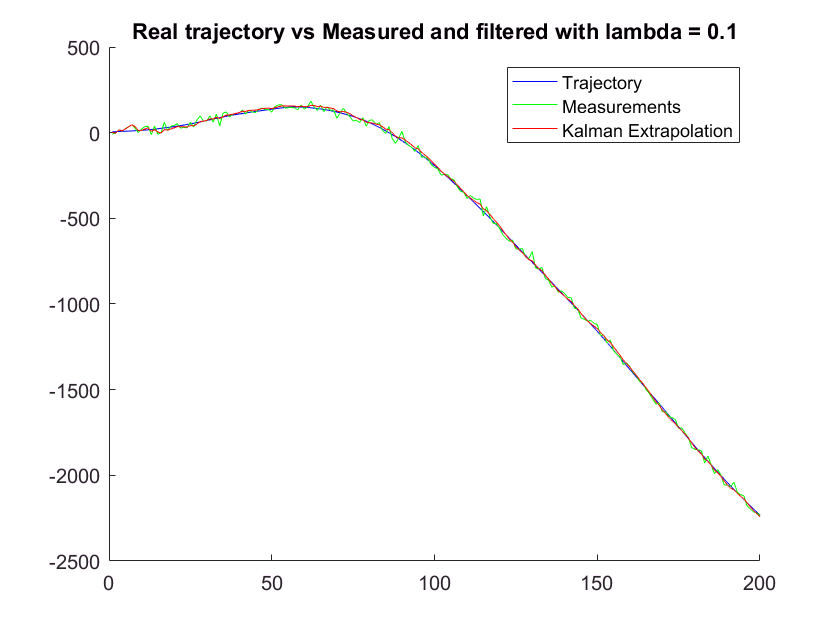

% figure; hold on
%     plot(X,'blue');
%     plot(Z, 'green');
%     plot(Xk(1,:), 'red');
%     title( ['Real trajectory vs Measured and filtered with lambda = ', num2str(lambda) ] );
%     legend('Trajectory', 'Measurements', 'Kalman Extrapolation');

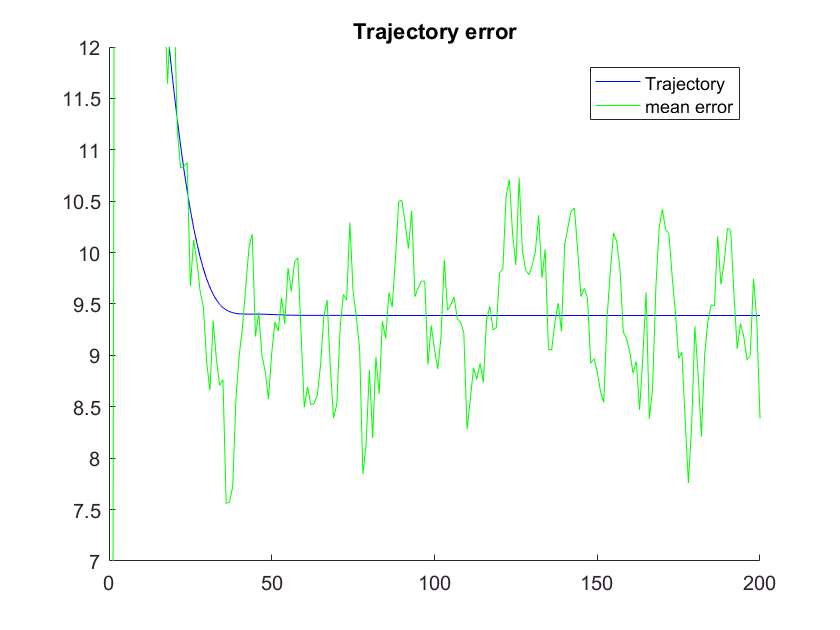

% 
% plotStartIndex=1;    
% figure; hold on;
%     plot(SigmaX(1, plotStartIndex:end),'blue');
%     plot(FinalError(1, plotStartIndex:end), 'green');
%     axis([0 n 7 12])
%     title('Trajectory error');
%     legend('Trajectory', 'mean error');

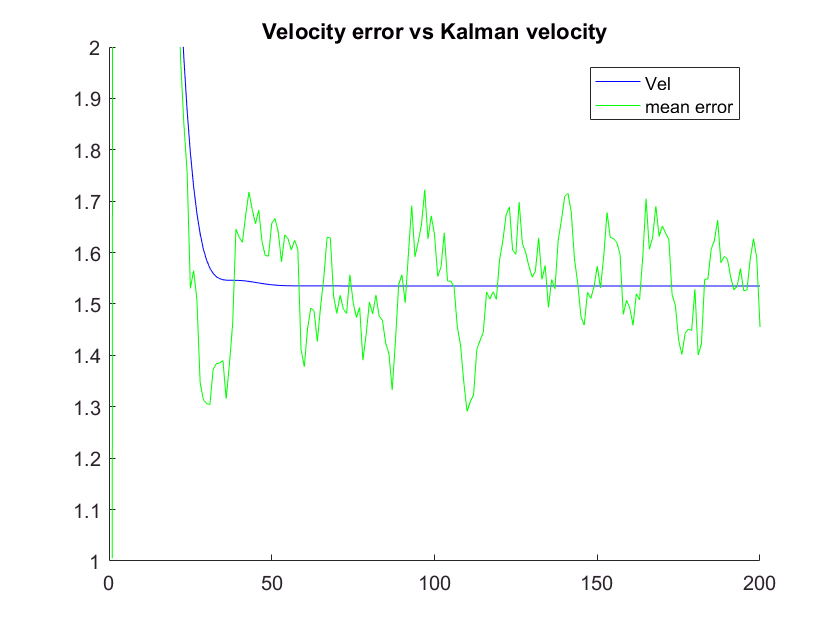

%     
% figure; hold on;
%     plot(SigmaX(2, plotStartIndex:end),'blue');
%     plot(FinalError(2, plotStartIndex:end), 'green');
%     axis([0 n 1 2])
%     title('Velocity error vs Kalman velocity');
%     legend('Vel', 'mean error');

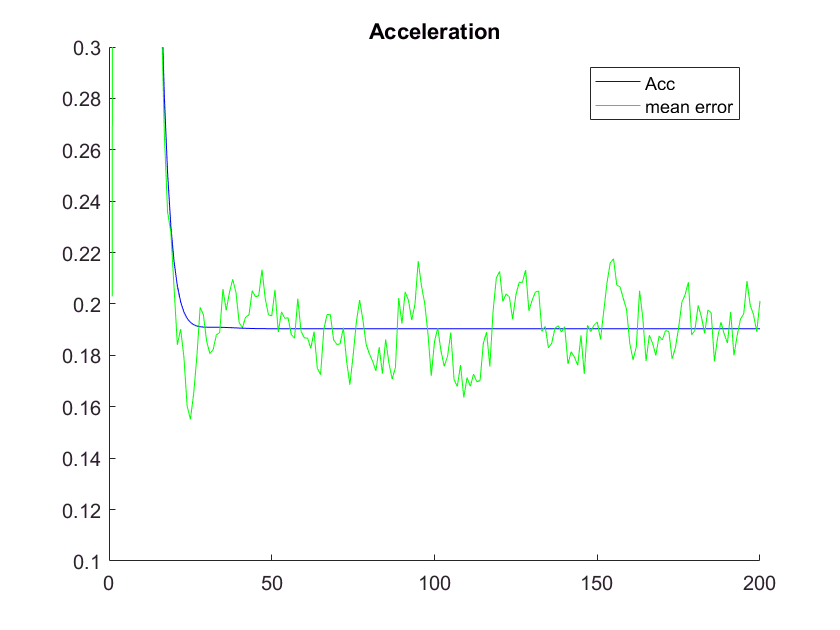

%     
% figure; hold on;
%     plot(SigmaX(3, plotStartIndex:end),'blue');
%     plot(FinalError(3, plotStartIndex:end), 'green');
%     axis([0 n 0.1 0.3])
%     title('Acceleration');
%     legend('Acc', 'mean error');

% 
